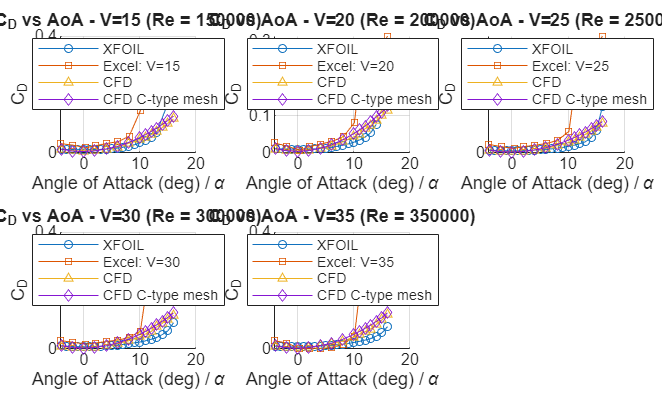

% compare_cd_all_graphs_only_option1.m

excelFile = "C:\Users\marke\Desktop\university\semester 8\Thesis\experiment\all series (Repaired).xlsx";
sheetNames = ["V=15", "V=20", "V=25", "V=30", "V=35"];

xfoilFiles = [ ...
    "C:\Users\marke\Desktop\XFOIL6.99\naca0012_150k_v15", ...
    "C:\Users\marke\Desktop\XFOIL6.99\naca0012_200k_v20", ...
    "C:\Users\marke\Desktop\XFOIL6.99\naca0012_250k_v25", ...
    "C:\Users\marke\Desktop\XFOIL6.99\naca0012_300k_v30", ...
    "C:\Users\marke\Desktop\XFOIL6.99\naca0012_350k_v35" ...
];

cfdCSV = "\\wsl.localhost\Ubuntu-22.04\home\mteggeri\OpenFOAM\mteggeri-13\run\naca0012_coefficients_summary.csv";
cfdCmeshFile = "\\wsl.localhost\Ubuntu-22.04\home\mteggeri\OpenFOAM\mteggeri-13\run\all_forceCoeffs_raw.dat";

n = numel(sheetNames);

% Option 1: known Reynolds numbers matching sheetNames order
Re_values = [150000, 200000, 250000, 300000, 350000];

Tc = readtable(cfdCSV, 'FileType','text');

optsC = delimitedTextImportOptions("NumVariables",6);
optsC.Delimiter = {' ','\t'};
optsC.ConsecutiveDelimitersRule = "join";
optsC.VariableNames = {'Velocity','AoA','Iter','CM','CD','CL'};
optsC.VariableTypes = repmat("double",1,6);

Tcmesh = readtable(cfdCmeshFile, optsC);

figure;
tiledlayout(2,3, 'TileSpacing','compact', 'Padding','compact');

for i = 1:n
    ax = nexttile;
    hold(ax,'on');

    label = sheetNames(i);
    Re = Re_values(i);  % use provided Re for the title

    % --- XFOIL ---
    try
        [alpha_x, CD_x] = parseXfoilCD(xfoilFiles(i));
        plot(ax, alpha_x, CD_x, '-o', ...
            'MarkerSize',4, ...
            'DisplayName','XFOIL');
    catch ME
        warning('XFOIL read failed for %s: %s', xfoilFiles(i), ME.message);
    end

    % --- Excel sheet ---
    try
        T2 = readtable(excelFile, 'Sheet', label);
        [idxA2, idxCD2] = findColumnsCD(T2);

        alpha_e = T2{:, idxA2};
        CD_e = T2{:, idxCD2};

        plot(ax, alpha_e, CD_e, '-s', ...
            'MarkerSize',4, ...
            'DisplayName', ['Excel: ' char(label)]);
    catch ME
        warning('Excel read failed for sheet %s: %s', label, ME.message);
    end

    % --- CFD summary CSV ---
    try
        rows = matchCfdRows(Tc, label);

        if any(rows)
            Tc_sub = Tc(rows,:);
            [idxAc, idxCDc] = findColumnsCD(Tc_sub);

            alpha_c = double(Tc_sub{:, idxAc});
            CD_c = double(Tc_sub{:, idxCDc});

            [alpha_c, sidx] = sort(alpha_c);
            CD_c = CD_c(sidx);

            plot(ax, alpha_c, CD_c, '-^', ...
                'MarkerSize',4, ...
                'DisplayName','CFD');
        else
            warning('No CFD rows matched for %s.', label);
        end
    catch ME
        warning('CFD processing failed for %s: %s', label, ME.message);
    end

    % --- CFD C-type mesh ---
    try
        vnum = sscanf(char(label),'V=%d');
        rowsC = Tcmesh.Velocity == vnum;

        if any(rowsC)
            Tcmesh_sub = Tcmesh(rowsC,:);

            alpha_ct = double(Tcmesh_sub.AoA);
            CD_ct = double(Tcmesh_sub.CD);

            [alpha_ct, sidx] = sort(alpha_ct);
            CD_ct = CD_ct(sidx);

            plot(ax, alpha_ct, CD_ct, '-d', ...
                'MarkerSize',4, ...
                'DisplayName','CFD C-type mesh');
        else
            warning('No C-type CFD rows matched for %s.', label);
        end
    catch ME
        warning('C-type CFD processing failed for %s: %s', label, ME.message);
    end

    xlabel(ax, 'Angle of Attack (deg) / \alpha');
    ylabel(ax, 'C_D');
    title(ax, sprintf('C_D vs AoA - %s (Re = %d)', label, Re));
    legend(ax, 'Location', 'best');
    grid(ax, 'on');
    hold(ax,'off');
end


%% Local helper functions

function [idxA, idxCD] = findColumnsCD(T)
    vars = lower(T.Properties.VariableNames);

    idxA = find(contains(vars, {'alpha','aoa','angle'}), 1);
    idxCD = find(contains(vars, {'cd','c_d','drag','drag_coeff'}), 1);

    if isempty(idxA) || isempty(idxCD)
        numericCols = varfun(@isnumeric, T, 'OutputFormat','uniform');
        cols = find(numericCols);

        if numel(cols) >= 3
            if isempty(idxA), idxA = cols(1); end
            if isempty(idxCD), idxCD = cols(3); end
        elseif numel(cols) >= 2
            if isempty(idxA), idxA = cols(1); end
            if isempty(idxCD), idxCD = cols(2); end
        else
            error('Cannot detect AoA and CD columns in table.');
        end
    end
end

function rows = matchCfdRows(Tc, label)
    vars = lower(Tc.Properties.VariableNames);
    rows = false(height(Tc),1);

    numVelIdx = find(contains(vars,{'vel','velocity','uinf','speed','v'}), 1);

    if ~isempty(numVelIdx)
        varname = Tc.Properties.VariableNames{numVelIdx};
        col = Tc.(varname);
        nrows = height(Tc);
        vnum = nan(nrows,1);

        if isnumeric(col)
            vnum = double(col);
        elseif iscell(col)
            for k = 1:nrows
                vnum(k) = tryStr2num(col{k});
            end
        elseif ischar(col)
            s = cellstr(col);
            for k = 1:nrows
                vnum(k) = tryStr2num(s{k});
            end
        elseif isstring(col)
            for k = 1:nrows
                vnum(k) = tryStr2num(col(k));
            end
        end

        numLabel = sscanf(char(label),'V=%d');
        if isempty(numLabel)
            numLabel = sscanf(char(label),'V%d');
        end

        if ~isempty(numLabel)
            rows = vnum == numLabel;
        end
    end

    if ~any(rows)
        cellMat = table2cell(Tc);
        [r,c] = size(cellMat);
        strMat = strings(r,c);

        for rr = 1:r
            for cc = 1:c
                val = cellMat{rr,cc};

                if isempty(val)
                    strMat(rr,cc) = "";
                elseif isnumeric(val)
                    strMat(rr,cc) = string(val);
                elseif isstring(val)
                    strMat(rr,cc) = val;
                elseif ischar(val)
                    strMat(rr,cc) = string(val);
                elseif iscell(val)
                    if isempty(val)
                        strMat(rr,cc) = "";
                    else
                        strMat(rr,cc) = string(val{1});
                    end
                else
                    strMat(rr,cc) = string(mat2str(val));
                end
            end
        end

        rowstr = join(strMat, ' ', 2);

        numOnly = char(extractAfter(char(label),'='));
        variants = unique([erase(char(label),'='), char(label), numOnly]);

        for k = 1:numel(variants)
            if ~isempty(variants{k})
                rows = rows | contains(rowstr, variants{k}, 'IgnoreCase', true);
            end
        end
    end
end

function n = tryStr2num(x)
    if isempty(x)
        n = NaN;
    elseif isnumeric(x)
        n = double(x);
    elseif ischar(x) || isstring(x)
        s = string(x);
        s = strrep(s, 'm/s', '');
        s = strrep(s, 'V=', '');
        s = strtrim(s);
        n = str2double(s);
    elseif iscell(x)
        if isempty(x)
            n = NaN;
        else
            n = tryStr2num(x{1});
        end
    else
        n = NaN;
    end
end

function [alpha, CD] = parseXfoilCD(fname)
    try
        T = readtable(fname, 'FileType','text');
        vars = lower(T.Properties.VariableNames);

        idxA = find(contains(vars,'alpha') | contains(vars,'aoa'),1);
        idxCD = find(contains(vars,'cd') | contains(vars,'drag'),1);

        if isempty(idxA) || isempty(idxCD)
            numericCols = varfun(@isnumeric, T, 'OutputFormat','uniform');
            cols = find(numericCols);

            if numel(cols) < 3
                error('XFOIL_parse_fail');
            end

            idxA = cols(1);
            idxCD = cols(3);
        end

        alpha = T{:, idxA};
        CD = T{:, idxCD};

        alpha = alpha(:);
        CD = CD(:);

        return;
    catch
        fid = fopen(fname,'r');

        if fid < 0
            error('Cannot open XFOIL file: %s', fname);
        end

        data = readmatrix(fname, 'FileType','text');

        if size(data,2) < 3
            error('XFOIL file does not contain enough columns for CD: %s', fname);
        end

        alpha = data(:,1);
        CD = data(:,3);
    end
end
